# 中山大学电子与通信工程学院

# 《数字信号处理实验》实验报告

## 实验五 快速傅里叶变换、时频域抽样及数字滤波器

## 一、实验目的

- 了解使用快速傅里叶变换（FFT）计算有限长序列和无限长序列信号频谱方法

- 掌握MATLAB进行快速傅里叶变换时常用的子函数

- 了解MATLAB进行时域抽样与信号重建方法

- 掌握采样频率的确定方法和内插公式的编程

- 了解由频谱通过IFFT计算连续时间信号方法

- 掌握MATLAB进行频域抽样与恢复时程序编写方法

- 加深对数字滤波器分类与结构的了解

- 掌握数字滤波器各种结构相互间的转换方法与MATLAB子函数

## 二、实验要求

- 每个实验内容都要清晰展示实验过程和实验结果。

- 绘图时必须明确标出各个坐标轴的意义和单位。

- 绘制多个子图时要明确标出各个子图所画的内容。

- 绘制多个信号时采用不同的线型和颜色区分、添加图例。

- 严禁抄袭、复制，发现雷同报告或代码双方成绩均作废！！

## 三、实验原理

1. 快速傅里叶变换（FFT）

        设序列x(n)的长度为N，且满足$\mathrm{N}=2^M$，M为自然数。按n的奇偶把x(n)分解为两个$\frac{N}{2}$的子序列


$$x_1 {\left(r\right)}=x{\left(2r\right)},\ \ \ r=0,1,\ \dots \ \ ,\frac{N}{2}-1$$



$$x_2 {\left(r\right)}=x{\left(2r+1\right)},\ \ r=0,1,\ \dots \ \ ,\frac{N}{2}-1$$



$$\mathrm{X}{\left(\mathrm{k}\right)}=\sum_{k=0}^{\frac{N}{2}\ -1} x_1 {\left(r\right)}W_{\frac{N}{2}}^{kr} +W_N^k \sum_{r=0}^{\frac{N}{2}\ -1} x_2 \left(r\right)W_{\frac{N}{2}}^{kr}$$


$=X_1 {\left(k\right)}+W_N^k X_2 \left(k\right)$k=0,1, … N-1

        其中$X_1 {\left(k\right)}$和$X_2 {\left(k\right)}$是$x_1 {\left(r\right)}$和$x_2 {\left(r\right)}$的$\frac{N}{2}$点DFT。

        X(k)的N点DFT可分解为两个$\frac{N}{2}$点的DFT并进行蝶式运算。由于$X_1 {\left(k\right)}$和$X_2 {\left(k\right)}$以为$\frac{N}{2}$周期，且$W_N^{\frac{k+N}{2}} =-W_N^k$，因此

$\mathrm{X}{\left(\mathrm{k}\right)}=X_1 {\left(k\right)}+W_N^k X_2 \left(k\right)$k=0,1, … N-1

$\mathrm{X}{\left(\mathrm{k}+\frac{N}{2}\right)}=X_1 {\left(k\right)}-W_N^k X_2 \left(k\right)$k=0,1, … N-1

2.FFT计算有限长序列的频谱

        一个序号$n_1$从$n_2$到的时域有限长序列x(n)，它的频谱$\mathrm{X}\left(e^{jw} \right)$定义为它的离散傅里叶变换，且在奈奎斯特(Nyquist)频率范围内有界且连续。序列的长度为N，则$\mathrm{N}=n_1 -n_2$。计算x(n)的离散傅里叶变换(DFT)得到的是$\mathrm{X}\left(e^{jw} \right)$的N个样本点$\mathrm{X}\left(e^{jw_k } \right)$。其中数字频率为


$$w_k =\mathrm{k}{\left(\frac{2\pi }{N}\right)}=kdw$$


        式中：dw为数字频率的分辨率；k取对应-(N-1)/2到(N-1)/2区间的整数。

        在实际使用中，往往要求计算出信号以模拟频率为横坐标的频谱，此时对应的模拟频率为


$$\Omega_k =\frac{w_k }{T_s }=k{\left(\frac{2\pi }{NT_s }\right)}=k{\left(\frac{2\pi }{L}\right)}=kD$$


        式中：D为模拟频率的分辨率或频率间隔；$T_s$为采样信号的周期，$T_s =\frac{1}{F_s }$；定义信号时域长度L=N$T_s$。

        在使用FFT进行DFT的高效运算时，一般不直接用n从到的x(n)，而是取的主值区间(n=0，1，…，N-1)的数据，经FFT将产生N个数据，定位在k=0,1,…,N-1的数字频率点上，即对应$\left\lbrack 0,2\pi \right\rbrack$。如果要显示范围$\left\lbrack -\pi ,\pi \right\rbrack$的频谱，则可以使用fftshift(X)进行位移。

3. 用 FFT计算无限长序列的频谱

        用 FFT进行无限长序列的频谱计算，首先要将无限长序列截断成一个有限长序列。序列长度的取值对频谱有较大的影响,带来的问题是引起频谱的泄漏和波动。

4.时域抽样与信号的重建

        离散时间信号大多由连续时间信号(模拟信号)抽样获得。在模拟信号进行数字化处理的过程中,主要经过A/D转换、数字信号处理、D/A转换和低通滤波等过程，如图所示。其中，A/D转换器的作用是将模拟信号讲行抽样、量化、编码，变成数字信号。经过处理后的数字信号则由D/A转换器重新恢复成模拟信号。

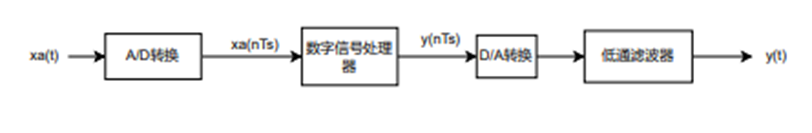

        如果A/D转换电路输出的信号频谱已经发生了混叠现象，则信号再经过后面的数字信号处理电路和D/A转换电路就没有实际使用的意义了。因此，信号进行A/D转换时,采样频率的确定是非常重要的。

        在信号进行处理的过程中，要使有限带宽信号$x_a \left(t\right)$被抽样后能够不失真地还原出原模拟信号，抽样信号p(t)的周期$T_s$及抽样频率$F_s$的取值必服从奈奎斯特(Nyquist)定理。假定的最高频率为$f_m$，则应有$F_s \ge 2f_m$，即$\Omega_s \ge 2\Omega_m$。

        由于$F_s$的取值符合大于两倍的信号最高频率$f_m$，因此只要经过一个低通滤波器，抽样信号$\hat{x_a } \left(t\right)$就能不失真地还原出原模拟信号。反之，如果$F_s$的取值小于两倍的信号最高频率$f_m$，则频谱$\left|\hat{X_a } {\left(w\right)}\left|\right.$将发生混叠，抽样信号$\hat{x_a } \left(t\right)$将无法不失真地还原出原模拟信号。时域信号重建过程如图所示：

        时域信号重建过程如图所示：

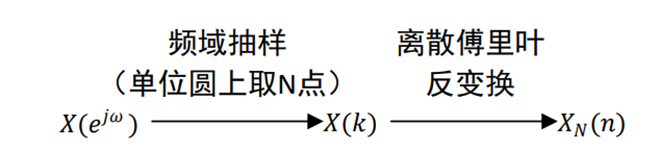

        从理论学习可知，在单位圆上对任意序列的z变换等间隔采样N点得到:


$$X{\left(k\right)}=X{\left(z\right)}{\left|\right.}_{z=e^{j\frac{2\pi }{N}k} } =\sum_{n=-\infty }^{\infty } x\left(n\right)e^{j\frac{2\pi }{N}nk} ,\ \ \ k=0,1,\dots ,N-1$$


        该式实现了序列在频域的抽样。

        由理论学习又知，频域抽样定理由下列公式表述:


$$\overset{~}{x} {\left(n\right)}=\sum_{r=-\infty }^{\infty } x\left(n+rN\right)$$


        表明对一个频谱采样后经IDFT生成的周期序列x(n)是原非周期序列x(n)的周期延拓序列，其时域周期等于频域抽样点数N。

        假定有限长序列x(n)的长度为M,频域抽样点数为N,则原时域信号不失真地由频域抽样恢复的条件如下:

        (1)如果x(n)不是有限长序列，则必然造成混叠现象，产生误差。

        (2) 如果x(n)是有限长序列，且频域抽样点数N小于序列长度M(即N<M)，则x(n)以N为周期进行延拓也将造成混叠，从$\overset{~}{x} \left(n\right)$中不能无失真地恢复出原信号x(n)。

        (3)如果x(n)是有限长序列，且频域抽样点数N大于或等于序列长度M(即N≥M)，则从$\overset{~}{x} \left(n\right)$中能无失真地恢复出原信号x(n)，即

$x_N {\left(n\right)}=\overset{~}{x_N } {\left(n\right)}R_N {\left(n\right)}=\sum_{r=-\infty }^{\infty } x\left(n+rN\right)R_N \left(n\right)$=x(n)

5.数字滤波器的分类

        离散LSI系统对信号的响应过程实际.上就是对信号进行滤波的过程。因此,离散LSI系统又称为数字滤波器。数字滤波器从滤波功能上可以分为低通、高通、带通、带阻以及全通滤波器;根据系统的单位冲激响应的特性，又可以分为有限长单位冲激响应滤波器(FIR)和无限长单位冲激响应滤波器(IIR)。

        一个离散LSI系统可以用系统函数来表示：


$$H{\left(z\right)}=\frac{Y\left(z\right)}{X\left(z\right)}=\frac{b\left(z\right)}{a\left(z\right)}=\frac{\sum_{m=0}^M b_m z^{-m} }{1+\sum_{k=1}^N a_k z^{-k} }=\frac{b_0 +b_1 z^{-1} +\dots +b_m z^{-m} }{1+a_1 z^{-1} +\dots +a_k z^{-k} }$$


        也可以用差分方程来表示：  

  
$$y{\left(n\right)}+\sum_{k=1}^N a_k y\left(n-k\right)=\sum_{m=0}^M b_m x\left(n-m\right)$$


        以上两个公式中，当$a_k$至少有一个不为0时，则在有限2平面上存在极点，表达的是一个IIR数字滤波器;当$a_k$全都为0时，系统不存在极点，表达的是一个FIR数字滤波器。FIR数字滤波器可以看成是IIR数字滤波器的ax全都为0时的一个特例。IIR数字滤波器的基本结构分为直接I型、直接I型、级联型和并联型。

        FIR数字滤波器的基本结构分为横截型(又称直接型或卷积型)、级联型、线性相位型及频率采样型等。另外，滤波器的-种新型结构格型结构也逐步投入应用，具有全零点FIR系统格型结构、全极点IIR系统格型结构以及全零极点IIR系统格型结构。

## 四、实验所用MATLAB函数

- fft函数：快速傅里叶变换，计算序列的离散傅里叶变换

- ifft函数：与fft函数相照应，计算序列离散傅里叶变换后的离散傅里叶逆变换

- fftshift函数：对fft的输出进行重新排列，将零频分量移动到频谱中心

- tf2latc函数：将IIR系统由直接型转换为格型结构，调用格式为[K,C]=tf2latc[b,a]

## 五、实验内容、方法、代码与结果

### **题目1**：已知无限长序列$x\left(n\right)=0\ldotp 5^n \left(n\ge 0\right)$，采样周期$T_s =0\ldotp 2s$。要求序列长度$N$分别取8、32和64，使用FFT来计算其频谱。

**解答1**：

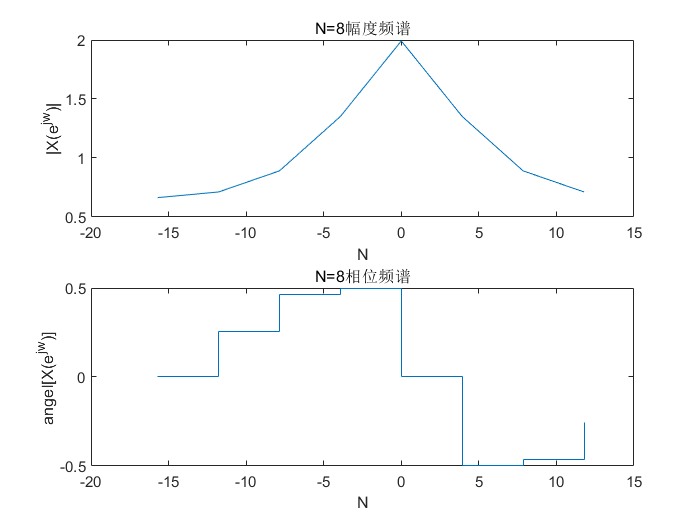

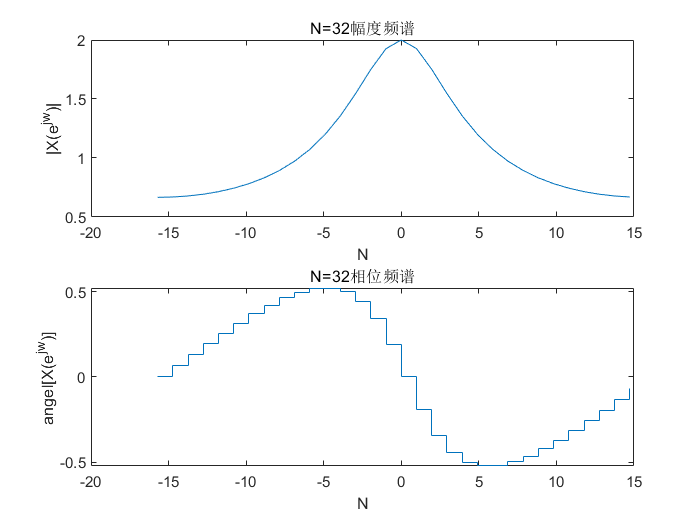

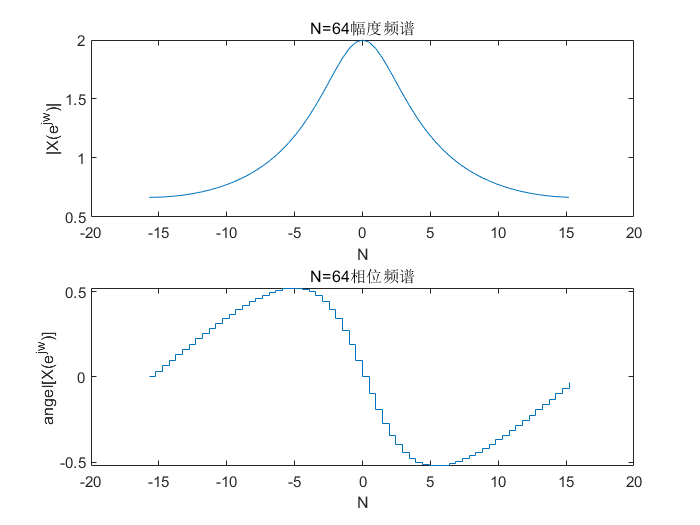

clc;
clear;
Ts=0.2;
Fs=1/Ts;
C=[8 32 64];
for r=0:2
   N=C(r+1);
   n=0:N-1;
   xn=0.5.^n;
   D=2*pi*Fs/N;
   k=floor(-(N-1)/2:(N-1)/2);
   Xk=fftshift(fft(xn,N));
   figure();
   subplot(2,1,1);
   plot(k*D,abs(Xk));
   title(['N=',num2str(N),'幅度频谱']);
   xlabel('N');
   ylabel('|X(e^{jw})|');
   subplot(2,1,2);
   stairs(k*D,angle(Xk));
   title(['N=',num2str(N),'相位频谱']);
   xlabel('N');
   ylabel('angel[X(e^{jw})]');
end

### **题目2**：已知连续时间信号$f\left(t\right)=\textrm{sinc}\left(t\right)$，取最高有限带宽频率$f_m =1\textrm{Hz}$：

### **①分别显示原连续时间信号波形和**${F_s =f}_m$、${F_s =2f}_m$、${F_s =3f}_m$三种情况下抽样信号的波形`；`

**②求解原连续信号波形和抽样信号所对应的幅度谱；**

**③用时域卷积的方法（内插公式）重建信号。**

**解答2**：

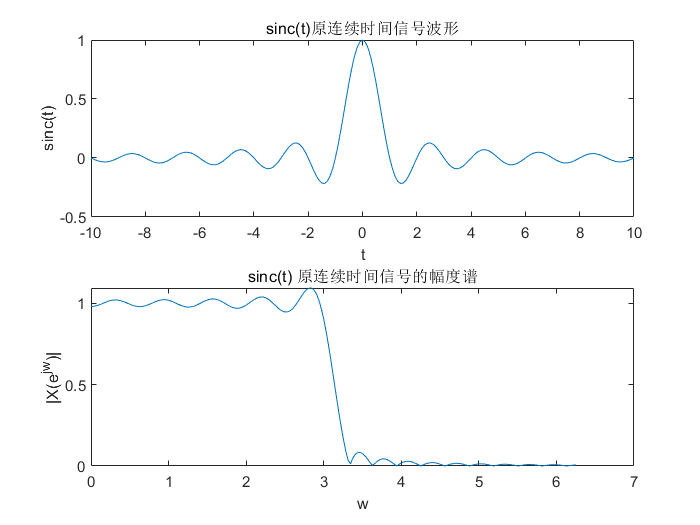

clc;
clear;
fm=1;
Fm=[1 2 3]*fm;
dt=0.1;
t=-10:dt:10;
ft_origin=sinc(t);
figure();
subplot(2,1,1);
plot(t,ft_origin);
title('sinc(t)原连续时间信号波形');
xlabel('t');
ylabel('sinc(t)');
N=length(t);
k=0:N-1;
wm=2*pi*fm;
w=k*wm/N;
F=ft_origin*exp(-1j*t'*w)*dt;
subplot(2,1,2);
plot(w,abs(F));
title('sinc(t) 原连续时间信号的幅度谱');
xlabel('w');
ylabel('|X(e^{jw})|');

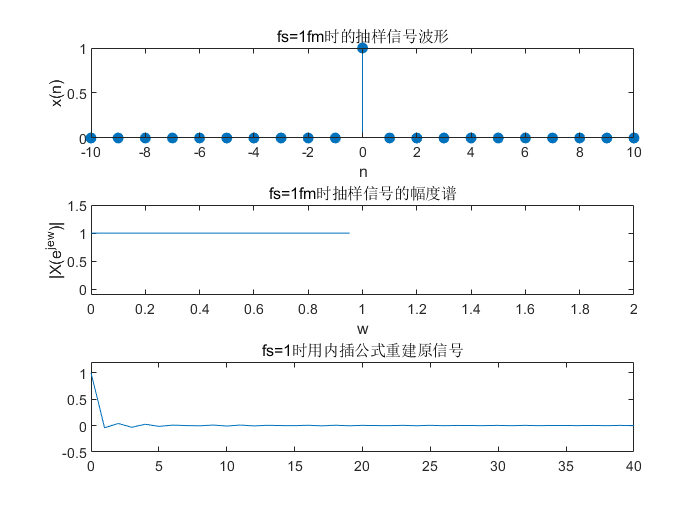

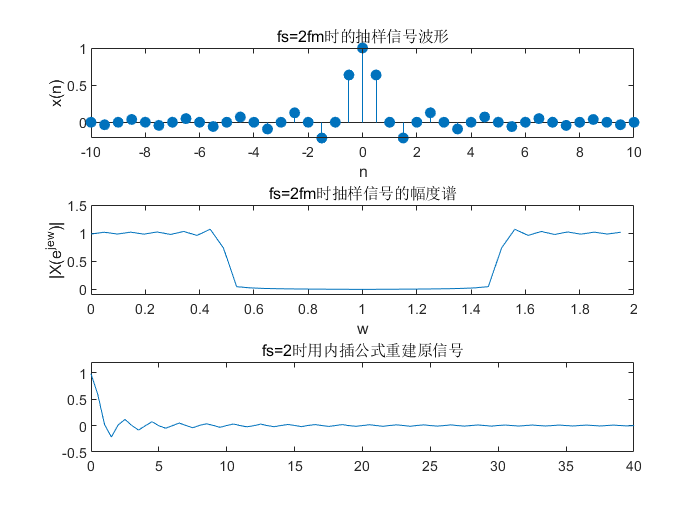

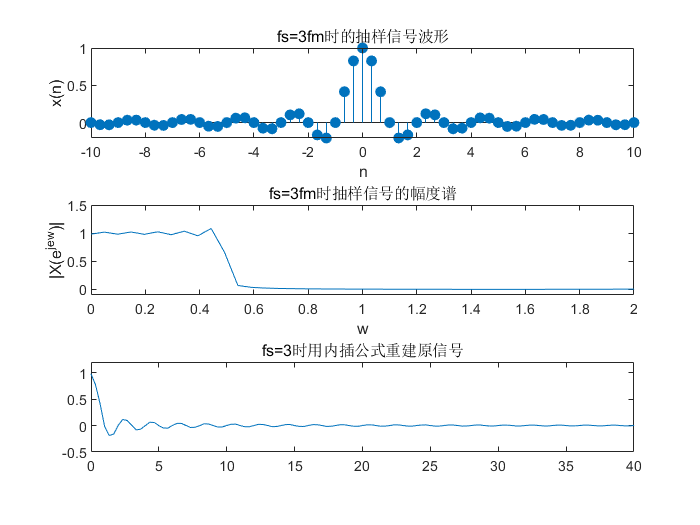

for r=1:3
    figure();
    Fs=Fm(r);
    Ts=1/Fs;
    n=-10:Ts:10;
    f=sinc(n);
    N=length(n);
    wm=2*pi*Fs;
    k=0:N-1;
    w=k*wm/N;
    subplot(3,1,1);
    stem(n,f,'filled')
    title(['fs=',num2str(r),'fm时的抽样信号波形']);
    xlabel('n');
    ylabel('x(n)');
    F=f*exp(-1j*n'*w)*Ts;
    subplot(3,1,2);
    plot(w/(2*pi),abs(F));
    title(['fs=',num2str(r),'fm时抽样信号的幅度谱'])
    xlabel('w');
    ylabel('|X(e^{jew})|');
    axis([0,2,-0.1,1.5]);
    subplot(3,1,3);
    n=0:200/Ts;
    t=0:Ts:200;
    x=sinc(n/Fs);%生成抽样信号
    T_N=ones(length(n),1)*t-n'*Ts*ones(1,length(t));
    xa=x*sinc(Fs*pi*T_N);
    plot(t,xa);
    title(['fs=',num2str(r),'时用内插公式重建原信号']);
    axis([0,40,-0.5,1.2]);
end

figure();
Fs=Fm(3);
Ts=1/Fs;
n=-10:Ts:10;
f=sinc(n);
N=length(n);
wm=2*pi*Fs;
k=0:N-1;
w=k*wm/N;
subplot(3,1,1);
stem(n,f,'filled')
title(['fs=',num2str(r),'fm时的抽样信号波形']);
xlabel('n');
ylabel('x(n)');
F=f*exp(-1j*n'*w)*Ts;
subplot(3,1,2);
plot(w/(2*pi),abs(F));
title(['fs=',num2str(r),'fm时抽样信号的幅度谱'])
xlabel('w');
ylabel('|X(e^{jew})|');
axis([0,2,-0.1,1.5]);
subplot(3,1,3);
n=0:200/Ts;
t=0:Ts:200;
x=sinc(n/Fs);%生成抽样信号
T_N=ones(length(n),1)*t-n'*Ts*ones(1,length(t));
xa=x*sinc(Fs*pi*T_N);
plot(t,xa);
title(['fs=',num2str(r),'时用内插公式重建原信号']);

### **题目3**：已知时间序列频谱为$X\left(e^{j\omega } \right)=2+4e^{-j\omega } +6e^{-\textrm{j2}\omega } +4e^{-\textrm{j3}\omega } +2e^{-\textrm{j4}\omega }$，分别取频域抽样点数$N$为3、5和10，用IFFT计算并求出其时间序列$x\left(n\right)$，用图形显示各时间序列。由此讨论原时域信号不失真地由频域抽样恢复的条件。

**解答3**：

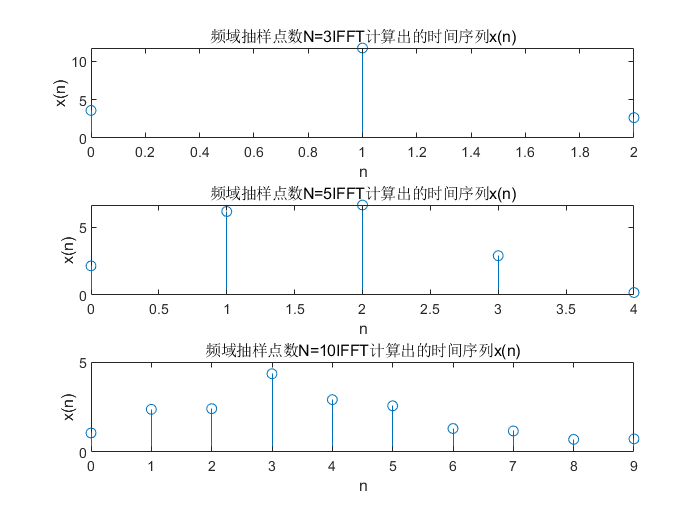

clc;
clear;
Ts=1;
N_all=[3,5,10];

for i=1:3
    N=N_all(i);
    D=2*pi/(Ts*N);  %求出模拟频率分辨率
    w=floor(-(N-1)/2:(N-1)/2);
    X=2+4*exp(-1j*w)+6*exp(-1j*2*w)+4*exp(-1j*3*w)+2*exp(-1j*4*w);
    n=0:N-1;
    x=ifft(X,N);
    subplot(3,1,i);
    stem(n*Ts,abs(x));
    title(['频域抽样点数N=',num2str(N),'IFFT计算出的时间序列x(n)'])
    xlabel('n');
    ylabel('x(n)')
end

disp('原时域信号不失真地由频域抽样恢复的条件:');

原时域信号不失真地由频域抽样恢复的条件:


disp('如果x(n)不是有限长序列，则必然产生混叠，产生误差;');

如果x(n)不是有限长序列，则必然产生混叠，产生误差;


disp(['如果x(n)是有限长序列，且频域抽样点数N小于序列长度M，则x(n)以N为周期进行周期延拓也将' ...
    '造成混叠，从中不能无失真的恢复出原信号x(n);']);

如果x(n)是有限长序列，且频域抽样点数N小于序列长度M，则x(n)以N为周期进行周期延拓也将造成混叠，从中不能无失真的恢复出原信号x(n);


disp('如果x(n)是有限长序列，且频域抽样点数N大于或等于序列长度M，则从中能无失真的恢复出原信号。');

如果x(n)是有限长序列，且频域抽样点数N大于或等于序列长度M，则从中能无失真的恢复出原信号。


### **题目4**：已知频率范围为$\left\lbrack -6\ldotp 28,6\ldotp 28\right\rbrack \textrm{rad}/s$间的频谱，在模拟频率$\left|\Omega_c \right|=3\ldotp 14$处幅度为1，其他范围幅度均为0。要求计算其连续信号$x_a \left(t\right)$，并用图形显示信号曲线。

**解答4**：

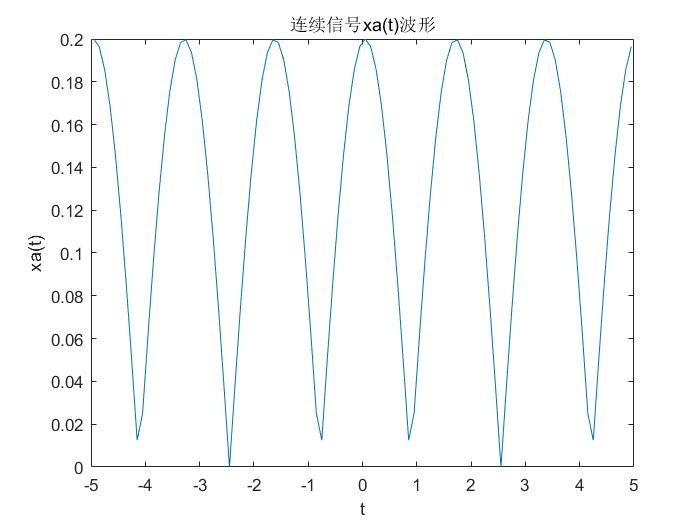

clc;
clear;
figure();
wc=3.14;
Ts=0.1;
N=100;
D=2*pi/(Ts*N);      
M=floor(wc/D);      
Xwa=[zeros(1,M),1,zeros(1,N-2*M+1),1,zeros(1,M-1)];
n=-(N-1)/2:(N-1)/2; 
xa=abs(fftshift(ifft(Xwa/Ts,N)));
plot(n*Ts,xa);
title('连续信号xa(t)波形')
xlabel('t');
ylabel('xa(t)');

### **题目5**：

### 已知一个IIR系统的传递函数为$H\left(Z\right)=\frac{0.1-0.4z^{-1} +0.4z^{-2} -0.1z^{-3} }{1+0.3z^{-1} +0.55z^{-2} +0.2z^{-3} }$

### 将其从直接型转换为级联型/并联型和格型结构，并画出各种结构的信号流图。

**解答5**：

clc;
clear;
b=[0.1,-0.4,0.4,-0.1];
a=[1,0.3,0.55,0.2];
disp('级联型结构:');

级联型结构:


[sos,g]=tf2sos(b,a);
disp('并联型结构:');

并联型结构:


[C,B,A]=dir2par(b,a)

C = -0.5000

B =    -0.5786    0.0148
    1.1786         0


A =     1.0000   -0.0519    0.5683
    1.0000    0.3519         0


disp('格型结构:');

格型结构:


[K,C]=tf2latc(b,a)

K =     0.1310
    0.5104
    0.2000


C =    -0.0431
   -0.4301
    0.4300
   -0.1000


        可以写出级联型传递函数为：$H{\left(z\right)}=0.1\textrm{∙}\frac{1-2.6180z^{-1} }{1+0.3519z^{-1} }\textrm{∙}\frac{1-1.3820z^{-1} +0.3820z^{-2} }{1-0.0519z^{-1} +0.5683z^{-2} }$

        级联型信号流图为：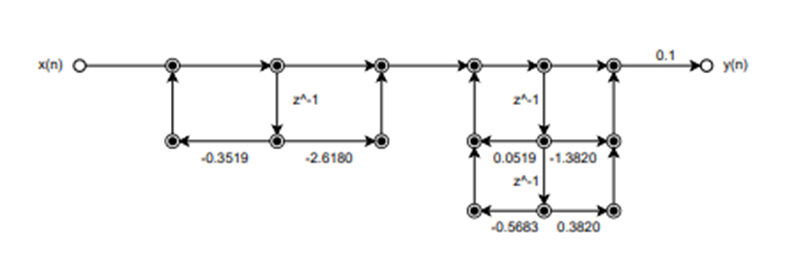

        并联型传递函数为：${\left(z\right)}=\frac{-0.2893+0.0001i}{1-{\left(0.0260+0.7534i\right)}z^{-1} }+\frac{-0.2893-0.0001i}{1-{\left(0.0260-0.7534i\right)}z^{-1} }+\frac{1.1786}{1-\left(-0.3519\right)z^{-1} }-0.5$

        并联型信号流图为：

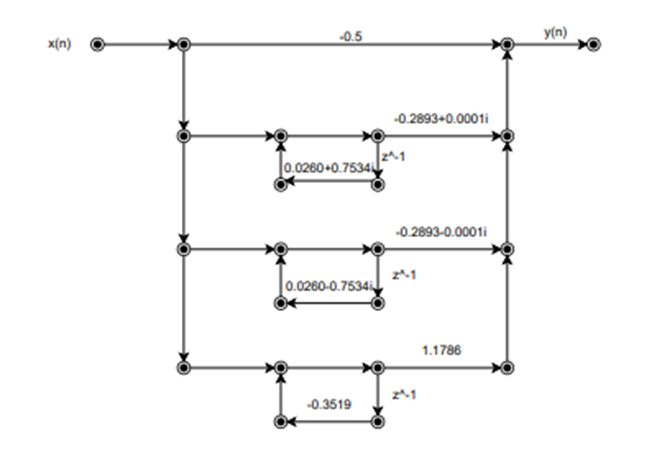

        格型结构流图：

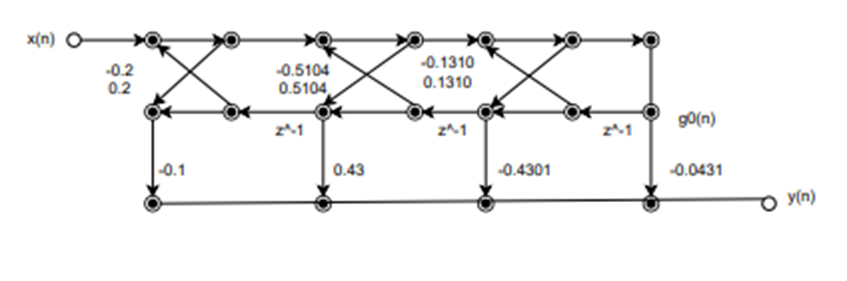

function [C,B,A] = dir2par(b,a)
% DIRECT-form to PARALLEL-form conversion
% --------------------------------------
% [C,B,A] = dir2par(b,a)
%  C = Polynomial part when length(b) >= length(a)
%  B = K by 2 matrix of real coefficients containing bk's
%  A = K by 3 matrix of real coefficients containing ak's
%  b = numerator polynomial coefficients of DIRECT form
%  a = denominator polynomial coefficients of DIRECT form
%

M = length(b); N = length(a);

[r1,p1,C] = residuez(b,a);
p = cplxpair(p1,10000000*eps);
I = cplxcomp(p1,p);
r = r1(I);

K = floor(N/2); B = zeros(K,2); A = zeros(K,3);
if K*2 == N; %N even, order of A(z) odd, one factor is first order
        for i=1:2:N-2
                Brow = r(i:1:i+1,:);
                Arow = p(i:1:i+1,:);
                [Brow,Arow] = residuez(Brow,Arow,[]);
                B(fix((i+1)/2),:) = real(Brow);
                A(fix((i+1)/2),:) = real(Arow);
        end
        [Brow,Arow] = residuez(r(N-1),p(N-1),[]);
        B(K,:) = [real(Brow) 0]; A(K,:) = [real(Arow) 0];
else
        for i=1:2:N-1
                Brow = r(i:1:i+1,:);
                Arow = p(i:1:i+1,:);
                [Brow,Arow] = residuez(Brow,Arow,[]);
                B(fix((i+1)/2),:) = real(Brow);
                A(fix((i+1)/2),:) = real(Arow);
        end
end
end

function I=cplxcomp(p1,p2)
I=[];
for j=1:1:length(p2)
for i=1:1:length(p1)
if (abs(p1(i)-p2(j))<0.0001)
I=[I,i];
end
end
end
I=I';
end